Consider a clamped-pinned beam modelled by von Karman beam theory.

clear all; close all; clc

## Model Setup

Building FE model
Assembling M,C,K matrices
Applying boundary conditions
Solving undamped eigenvalue problem
Frequencies / Hz
    4.8860
   15.8396
   33.0927
   56.7731
   87.1597


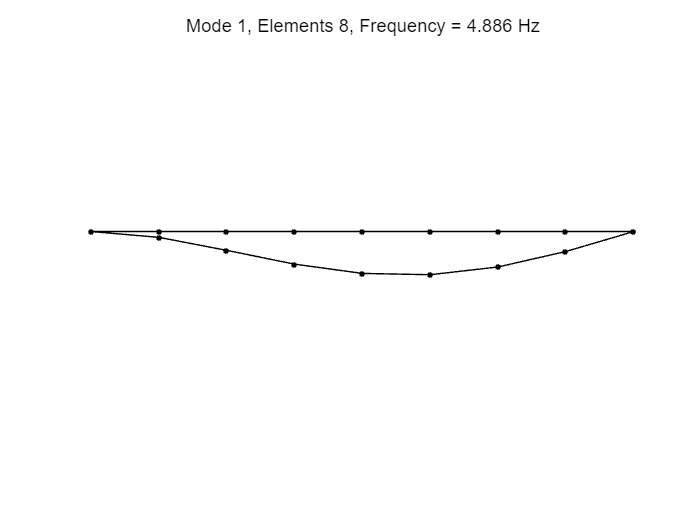

Getting nonlinearity coefficients
Assembling Tensors
Assembling external force vector


nElements = 8;
kappa = 1e5; % strong damping
[M,C,K,fnl,~,outdof] = build_model(nElements,kappa);

n = length(M);

#### Dynamical System Setup

Consider the following forced system


$$\mathbf{M}\ddot{\mathbf{x}}+\mathbf{C}\dot{\mathbf{x}}+\mathbf{K}\mathbf{x}+\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})=\epsilon\mathbf{f}^{ext}({\Omega}t),$$


which can be written in the first-order form as 


$$\mathbf{B}\dot{\mathbf{z}}	=\mathbf{Az}+\mathbf{F}(\mathbf{z})+\epsilon\mathbf{F}^{ext}({\phi}),\\\dot{\phi}	
=\Omega$$


where 


$$\mathbf{z}=\left[\begin{array}{c}\mathbf{x}\\\dot{\mathbf{x}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}-\mathbf{K} 
& \mathbf{0}\\\mathbf{0} & \mathbf{M}\end{array}\right],\mathbf{B}=\left[\begin{array}{cc}\mathbf{C} 
& \mathbf{M}\\\mathbf{M} & \mathbf{0}\end{array}\right],\quad\quad\mathbf{F}(\mathbf{z})=\left[\begin{array}{c}\mathbf{-\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})}\\\mathbf{0}\end{array}\right]$$


DS = DynamicalSystem();
set(DS,'M',M,'C',C,'K',K,'fnl',fnl);
set(DS.Options,'Emax',11,'Nmax',10,'notation','multiindex','outDOF',outdof)

Add external forcing and also control matrix

Bext     = zeros(n,1); Bext(outdof(2),1)=1; 
ExtForce = @(t) Bext*sin(20*t+15*t/(2+sin(t)));
epsilon  = 50;
set(DS,'D',Bext,'E',ExtForce,'epsilon',epsilon);

### Linear Modal analysis

[V,D,W] = DS.linear_spectral_analysis();

Due to high-dimensionality, we compute only the first 11 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 3.411040e-02
modal damping ratio for 2 mode is 1.105810e-01
modal damping ratio for 3 mode is 2.310303e-01
modal damping ratio for 4 mode is 3.963511e-01
modal damping ratio for 5 mode is 6.084896e-01
modal damping ratio for 6 mode is 8.705050e-01
modal damping ratio for 7 mode is 1.182038e+00
modal damping ratio for 8 mode is 1.644161e+00
modal damping ratio for 9 mode is 2.089910e+00
modal damping ratio for 10 mode is 2.665776e+00
modal damping ratio for 11 mode is 3.373412e+00

 The first 22 nonzero eigenvalues are given as 
   1.0e+04 *
  -0.0001 + 0.0031i
  -0.0001 - 0.0031i
  -0.0011 + 0.0099i
  -0.0011 - 0.0099i
  -0.0048 + 0.0202i
  -0.0048 - 0.0202i
  -0.0141 + 0.0328i
  -0.0141 - 0.0328i
  -0.0333 + 0.0435i
  -0.0333 - 0.04

## SSM Reduced dynamics - autonomous part

S = SSM(DS);
set(S.Options, 'reltol', 0.1,'notation','multiindex')
order = 5;

**Reduced dynamics simulation**

*Construction of initial condition*

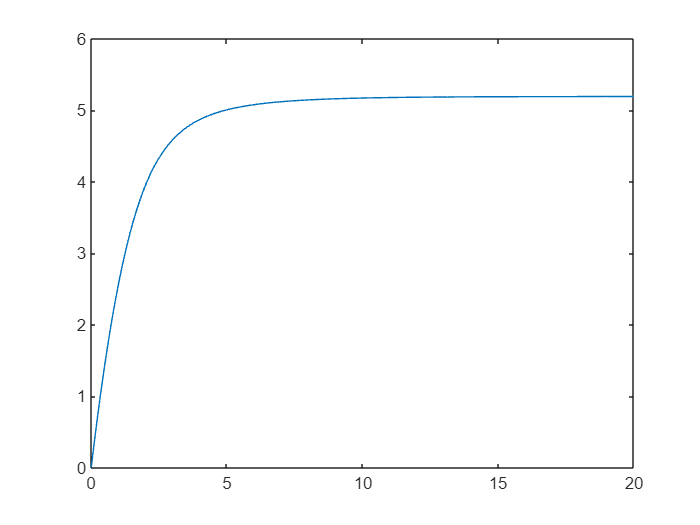

om = 2*pi/20;
nsteps = 500;
DSstatic = DynamicalSystem();
set(DSstatic,'M',M,'C',1000*C,'K',K,'fnl',fnl);
set(DSstatic.Options,'HarmonicForce',false);
fmidspan = zeros(n,1);
fmidspan(outdof(2)) = 1500;
Fmidspan = @(t) fmidspan;
set(DSstatic,'fext',Fmidspan);
[ts, xs, xf] = time_integration_transient(DSstatic,om,'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','ode15s','outdof',outdof,'init',zeros(2*n,1));
figure;
plot(ts,xs(:,2))


% master subspace
modes = [1 2 3 4];
S.choose_E(modes);

No (near) outer resonances detected in the (truncated) spectrum
sigma_out = 19121
(near) inner resonance detected for the following combination of master eigenvalues
     2     1     0     0
     1     2     0     0
     1     1     1     0
     1     1     0     1
These are in resonance with the follwing eigenvalues of the master subspace
  -1.0472 +30.6815i
  -1.0472 -30.6815i
 -11.0053 +98.9126i
 -11.0053 -98.9126i
sigma_in = 19121


% compute autonomous SSM coefficients
[W_0,R_0] = S.compute_whisker(order);

Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 7.63E-02 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 1.84E-01 MB
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 2.97E-01 MB
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 5.57E-01 MB


% construct initial condition
z0 = xf';

t0 = 0;
tf = 0.2;

## Linear model order reduction analysis

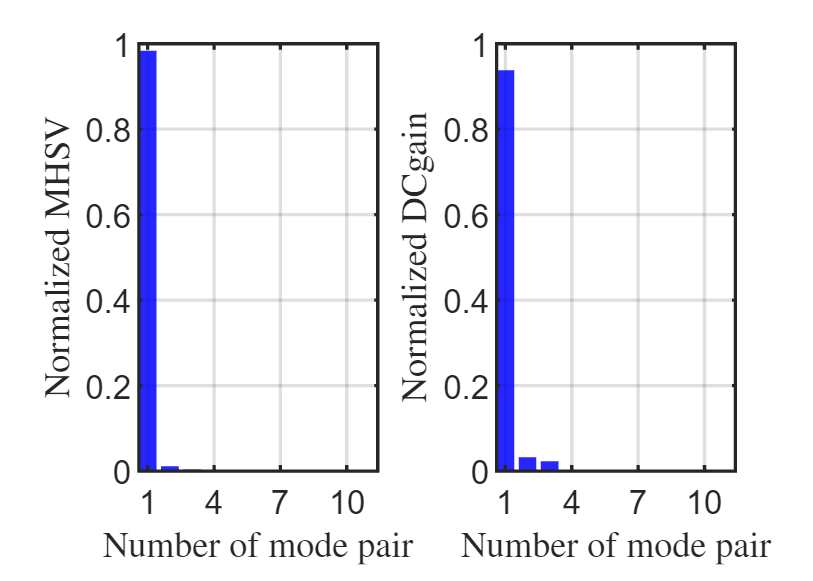

MHSV sum of the first 2 pairs
    0.9950
DCgain sum of the first 2 pairs
    0.9706


res = Linear_MOR(DS,11);

auData = construct_autoData(DS, modes, R_0);
cont   = struct();
cont.Q    = blkdiag(0.1*eye(n),zeros(n));
cont.Q    = blkdiag(0.1*eye(n),zeros(n));
cont.Rhat = 0.01;
cont.Mhat = eye(2*n)*0;


## Free Vibration

t0 = 0; t1 = 0.2;
om = 2*pi/t1;
set(DS,'u',[]);
[tfullwo, xfullwo] = time_integration_transient(DS,om,'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','ode15s','outdof',outdof,'init',z0,'ts',t0);

## Open loop control

t1 = tf;
tspan = linspace(t0,t1,nsteps);
traj_open = LQR_closed_loop(DS,z0,'linear',tspan,auData,W_0,modes,1:2,cont);

pl
  -1.1855 + 0.0405i
  -1.1855 - 0.0405i
  -0.0687 + 0.0076i
  -0.0687 - 0.0076i
p0
  -1.1855 + 0.0405i
  -1.1855 - 0.0405i
  -0.0687 + 0.0076i
  -0.0687 - 0.0076i
历时 0.069441 秒。
历时 0.040062 秒。
Time for backward simulation of Riccati ODE is 4.154110e-02
历时 0.099214 秒。
Time for backward simulation of compensated ODE is 1.935201e-01
历时 0.099954 秒。
Time for forward simulation of ODEs for modal coordinates is 1.016983e-01



om = 2*pi/t1;
ufun = @(t) transpose(interp1(traj_open.time,traj_open.ut',t));
set(DS,'u',ufun);
[tfullwc1, xfullwc1] = time_integration_transient(DS,om,'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','ode15s','outdof',outdof,'init',z0);

**plot**

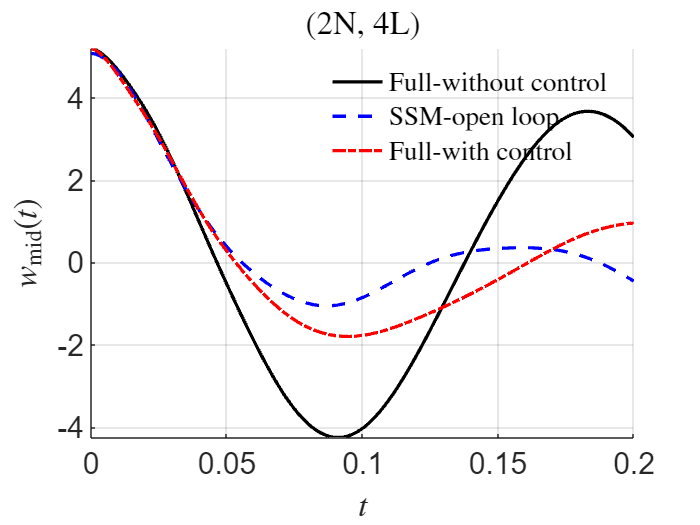

% displacement field

figure; hold on
plot(tfullwo, xfullwo(:,2),'k-','DisplayName', 'Full-without control','LineWidth',2);
plot(traj_open.time, traj_open.zt(2,:),'b--','DisplayName','SSM-open loop','LineWidth',2);
plot(tfullwc1, xfullwc1(:,2),'r-.','DisplayName', 'Full-with control','LineWidth',2);


legend('show','Interpreter',"latex"); legend boxoff
xlabel('$t$','Interpreter',"latex")
zk = strcat('$w_{\mathrm{mid}}(t)$');
ylabel(zk,'Interpreter','latex');
title('(4N, 2L)','Interpreter',"latex")
set(gca,'FontSize',18);
grid on, axis tight

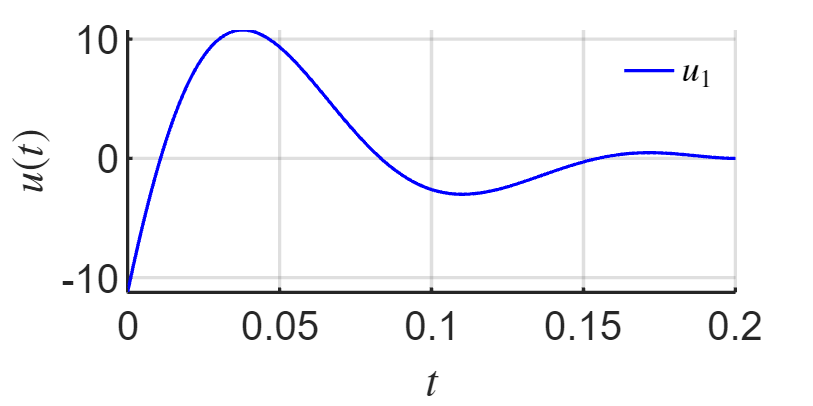




%  control input
figure; hold on;
plot(traj_open.time,traj_open.ut,'b-','DisplayName','SSM-open-control','DisplayName','$u_1$','LineWidth',2);

legend('show','Interpreter','latex'); legend boxoff
xlabel('$t$','Interpreter',"latex")
ylabel('$u(t)$','Interpreter','latex')
set(gca,'FontSize',24); grid on, axis tight

set(gca, 'LineWidth', 2);
set(gcf, 'Position', [0 0 800 400]);

% print('-depsc', 'OscillatorChain_ControlPolicy_outdof5_woFeedback.eps')
% print -djpeg -r300 OscillatorChain_ControlPolicy_outdof5_woFeedback.jpg;

## Closed loop control

**Full dynamics simulation - with control**

**Time interval - 1**

t0 = 0; 
t1 = 0.1;
tspan1 = linspace(t0,t1,nsteps);
traj1 = LQR_closed_loop(DS,z0,'linear',tspan1,auData,W_0,modes,1:2,cont);

pl
  -1.1855 + 0.0405i
  -1.1855 - 0.0405i
  -0.0687 + 0.0076i
  -0.0687 - 0.0076i
p0
  -1.1855 + 0.0405i
  -1.1855 - 0.0405i
  -0.0687 + 0.0076i
  -0.0687 - 0.0076i
历时 0.031435 秒。
历时 0.029674 秒。
Time for backward simulation of Riccati ODE is 3.002290e-02
历时 0.037212 秒。
Time for backward simulation of compensated ODE is 3.913400e-02
历时 0.026639 秒。
Time for forward simulation of ODEs for modal coordinates is 2.810720e-02


ufun1 = @(t) transpose(interp1(traj1.time,traj1.ut',t,'linear','extrap'));
set(DS,'u',ufun1);
[tfull1, xfull1,x1f,xt1] = time_integration_transient(DS,2*pi/(t1-t0),'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','ode15s','outdof',outdof,'init',z0);

**Time interval - 2**

t2 = 0.2;
tspan2 = linspace(t1,t2,nsteps);
traj2  = LQR_closed_loop(DS,x1f','linear',tspan2,auData,W_0,modes,1:2,cont);

pl
   0.4353 + 0.1408i
   0.4353 - 0.1408i
   0.0213 + 0.0157i
   0.0213 - 0.0157i
p0
   0.4353 + 0.1408i
   0.4353 - 0.1408i
   0.0213 + 0.0157i
   0.0213 - 0.0157i
历时 0.023802 秒。
历时 0.008715 秒。
Time for backward simulation of Riccati ODE is 8.988400e-03
历时 0.021308 秒。
Time for backward simulation of compensated ODE is 2.185680e-02
历时 0.012567 秒。
Time for forward simulation of ODEs for modal coordinates is 1.327230e-02



ufun2 = @(t) transpose(interp1(traj2.time,traj2.ut',t,'linear','extrap'));
set(DS,'u',ufun2);
[tfull2, xfull2,x2f,xt2] = time_integration_transient(DS,2*pi/(t2-t1),'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','ode15s','outdof',outdof,'init',x1f','ts',t1);


## Plot

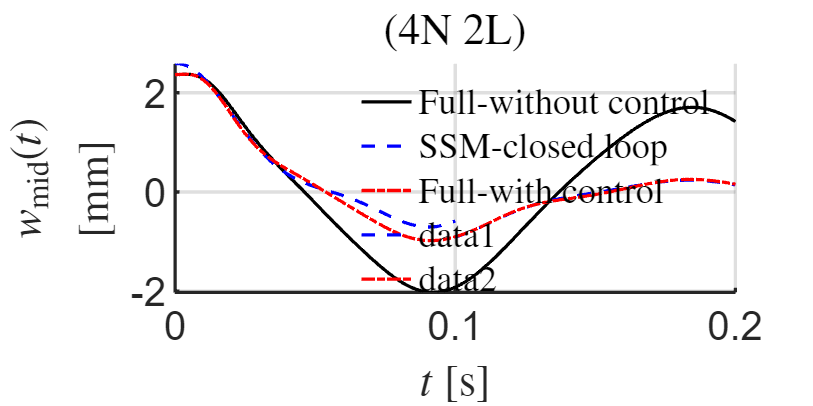

% outdof 5
figure; hold on
plot(tfullwo, xfullwo(:,1),'k-','DisplayName', 'Full-without control','LineWidth',2);

plot(traj1.time, traj1.zt(1,:),'b--','DisplayName','SSM-closed loop','LineWidth',2);
plot(tfull1, xfull1(:,1),'r-.','DisplayName', 'Full-with control','LineWidth',2);

plot(traj2.time, traj2.zt(1,:),'b--','LineWidth',2);
plot(tfull2, xfull2(:,1),'r-.','LineWidth',2);

legend('show','Interpreter','latex'); legend boxoff
xlabel('$t$ [s]','Interpreter',"latex")
zk = strcat('$$w_{\mathrm{mid}}(t)$$ [mm]');
ylabel(zk,'Interpreter','latex');
title('(4N 2L)','Interpreter','latex')
set(gca,'FontSize',24);
grid on, axis tight

set(gca, 'LineWidth', 2);
set(gcf, 'Position', [0 0 800 400]);

% print('-depsc', 'OscillatorChain_outdof5_woFeedback.eps')
% print -djpeg -r300 OscillatorChain_outdof5_woFeedback.jpg;


## Plot - control inputs

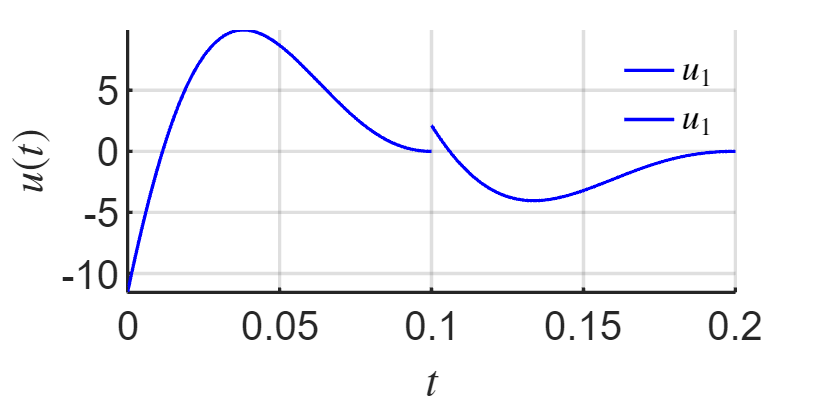

%  control input
figure; hold on;
plot(traj1.time,traj1.ut,'b-','DisplayName','SSM-open-control','DisplayName','$u_1$','LineWidth',2);
plot(traj2.time,traj2.ut,'b-','DisplayName','SSM-open-control','DisplayName','$u_1$','LineWidth',2);

legend('show','Interpreter','latex'); legend boxoff
xlabel('$t$','Interpreter',"latex")
ylabel('$u(t)$','Interpreter','latex')
set(gca,'FontSize',24); grid on, axis tight

set(gca, 'LineWidth', 2);
set(gcf, 'Position', [0 0 800 400]);